# Train a Network from Scratch

### Input

- `params` is a structure with fields from the Experiment Manager hyperparameter table.

#### Output

- `xTrain` and `yTrain` are a 4-D array of training images and a categorial vector of labels.

- `layers` is a layer graph that defines the neural network architecture.

- `options` is a `trainingOptions` object.

[xTrain, yTrain, layers, options] = TrainFromScratch_setup1();

## Train the network

Training on single CPU.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:03 |       10.94% |       12.01% |       2.6657 |       2.6514 |      1.0000e-04 |
|       1 |          50 |       00:00:07 |       64.84% |              |       1.3417 |              |      1.0000e-04 |
|       1 |         100 |       00:00:10 |       73.44% |              |       0.9849 |              |      1.0000e-04 |
|       1 |         150 |       00:00:13 |       75.00% |              |       0.8387 |   

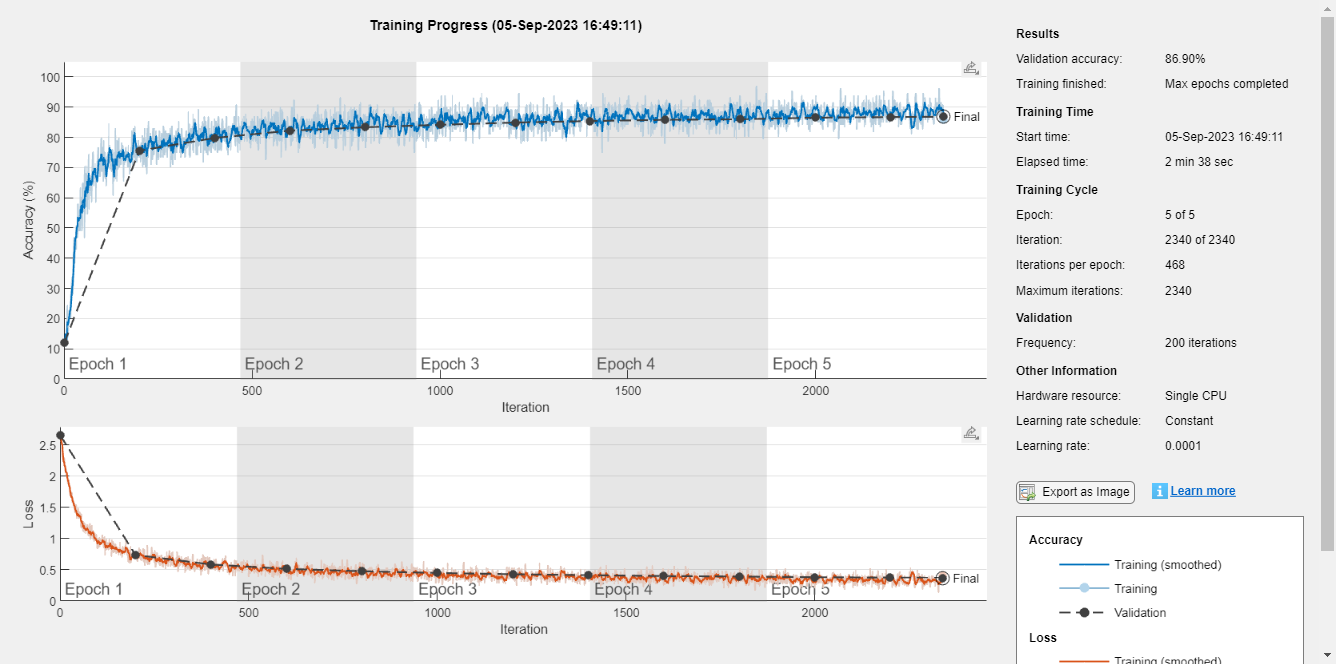

net = trainNetwork(xTrain, yTrain, layers, options);

function [xTrain, yTrain, layers, options] = TrainFromScratch_setup1()

#### Load Training Data

    data = load("../data/fashionMNIST.mat");
    yTrain = data.yTrain;
    yTest = data.yTest;
    xTrain = reshape(data.xTrain, 28, 28, 1, numel(yTrain));
    xTest = reshape(data.xTest, 28, 28, 1, numel(yTest));

#### Define Network Architecture

    layers = [  imageInputLayer([28 28 1])
                
                convolution2dLayer(3, 8, "Padding", "same")
                batchNormalizationLayer
                reluLayer
                
                maxPooling2dLayer(2, "Stride", 2)
                
                convolution2dLayer(3, 16, "Padding", "same")
                batchNormalizationLayer
                reluLayer
                
                maxPooling2dLayer(2, "Stride", 2)
                
                convolution2dLayer(3, 32, "Padding", "same")
                batchNormalizationLayer
                reluLayer
                
                fullyConnectedLayer(10)
                softmaxLayer
                classificationLayer];

#### Specify Training Options

Call the [`trainingOptions`](matlab:doc('trainingOptions')) function to specify the training options for the experiment. Read the hyperparameters specified in Experiment Manager by accessing the fields of the input `params`. For example, access the initial learning rate `myInitialLearnRate` defined in the hyperparameter table with the argument value `params.myInitialLearnRate`.

    options = trainingOptions(  "adam", ...
                                "InitialLearnRate", 0.0001,...
                                "MaxEpochs", 5, ... 
                                "ValidationData", {xTest yTest}, ...
                                "ValidationFrequency", 200,...
                                "Shuffle", "every-epoch",...
                                "Verbose", true,...
                                "Plots", "training-progress");
end